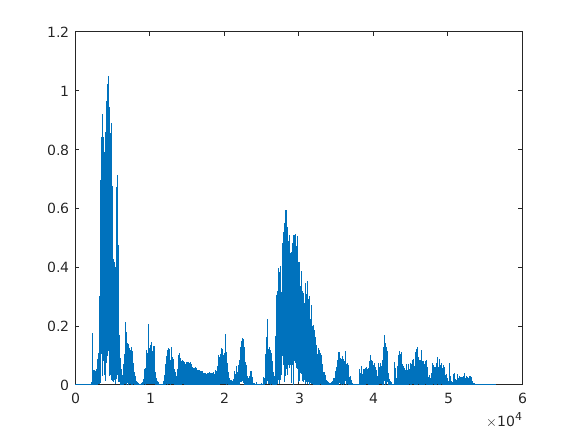

[data,fs] = audioread('sm1_filtered.wav');

t = [0 : 1/fs : length(data)/fs]; % time in sec
t = t(1:end - 1);
%remove dc component
data = data - mean(data);

%normalize data 
data = data / abs(max(data));

%get upper envelope

[U,L] = envelope(data);
plot(U)

%set max peak
m = mean(U)

m = 0.0472

mph = mean(U)/3

mph = 0.0157

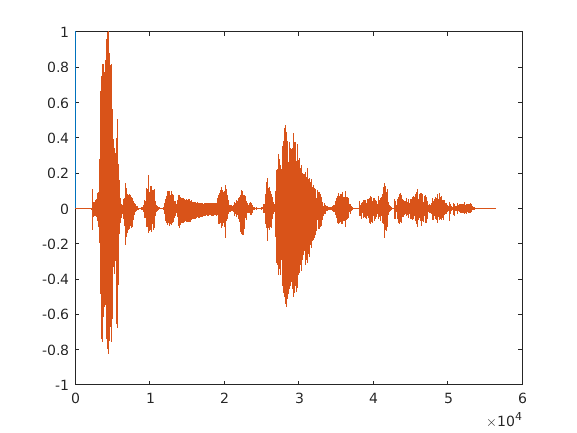


% find the peaks
[pks,ind] = findpeaks(U, 'MinPeakHeight', mph);

data_p = zeros(length(data),1);
data_p (ind) = 1;
figure;

plot(t, data_p, '-'); hold on; plot(data); hold off

j = 0;
for i = length(data_p)
    if data_p(i) == 1
        data_p(i) = pks(j)
    end
     j = j + 1;

end


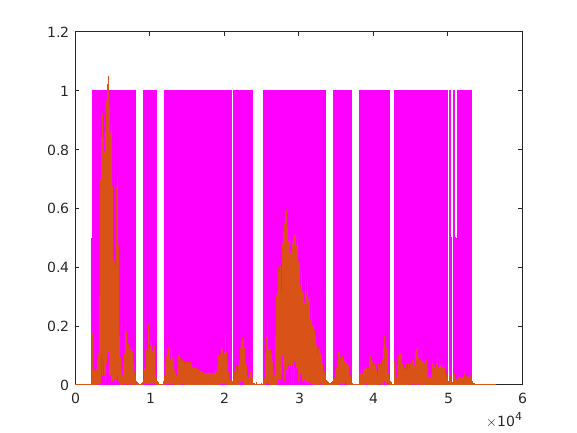

figure;
plot(data_p,'m','LineWidth',1);
hold on;
plot(U) ; 
hold off;

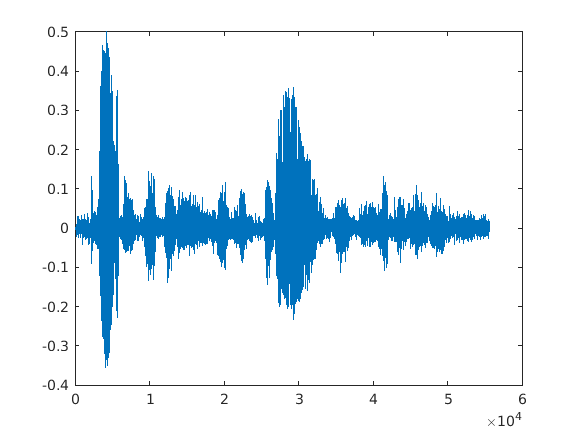

%testing it out with different recordings

[clndigit,fs] = audioread('sm1_LN.wav');
soundsc(clndigit)
figure;
plot(clndigit)

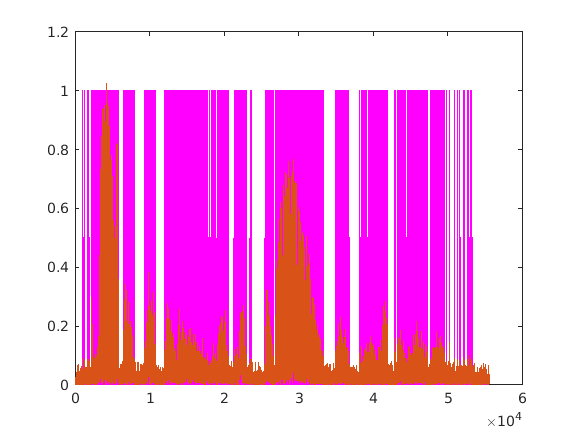



[manfr, enve, cln_index] = manualframe(clndigit);
figure;
plot(manfr,'m','LineWidth',1);
hold on;
plot(enve) ; 

hold off;

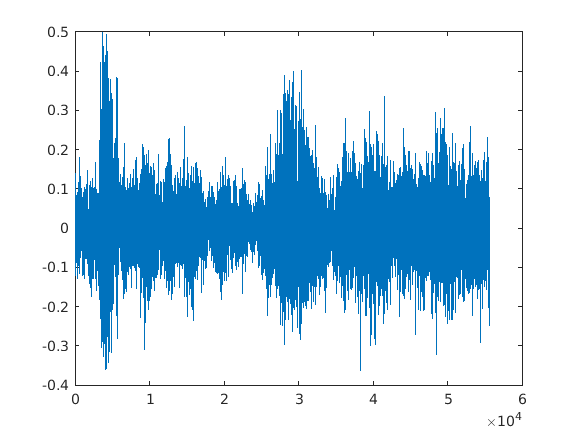

% testing with high noise signal
[ndigit,fs] = audioread('sm1_HN.wav');
soundsc(ndigit)
figure;
plot (ndigit)

m = mean(ndigit)

m = 0.0019

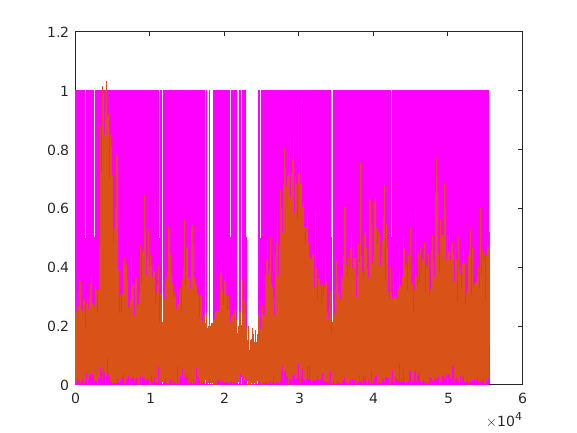

[nmanfr, nenve, , ndigit_index] = manualframe(ndigit);
figure;
plot(nmanfr,'m','LineWidth',1);
hold on;
plot(nenve) ; 

hold off; % from what I see it's safe to say that it becomes less and less accurate with noise

% didn't work at all for this 